function [x_final, x_history] = heavyBall(grad_f, x0, alpha, beta, max_iter)
% HEAVYBALL Performs optimization using the Heavy Ball method.
%
% Inputs:
%   grad_f      - A function handle to the gradient of the objective function.
%   x0          - The initial starting point (column vector).
%   alpha       - The learning rate (a small positive scalar).
%   beta        - The momentum parameter (scalar, typically ~0.9).
%   max_iter    - The maximum number of iterations.
%
% Outputs:
%   x_final     - The final optimized point.
%   x_history   - A matrix storing the position at each iteration.

    % Initialize variables
    x = x0;
    v = zeros(size(x0)); % Initialize momentum vector to zero
    x_history = zeros(length(x0), max_iter + 1);
    x_history(:, 1) = x;

    % Main optimization loop
    for k = 1:max_iter
        % Calculate the gradient at the current position
        g = grad_f(x);

        % Update the momentum vector
        % v_new = beta * v_old - alpha * gradient
        v = beta * v - alpha * g;
        
        % Update the position
        % x_new = x_old + v_new
        x = x + v;
        
        % Store the history for plotting
        x_history(:, k + 1) = x;
    end
    
    x_final = x;
end

function [x_final, x_history] = nesterovMomentum(grad_f, x0, alpha, beta, max_iter)
% NESTEROVMOMENTUM Performs optimization using Nesterov's Accelerated Gradient.
%
% Inputs:
%   grad_f      - A function handle to the gradient of the objective function.
%   x0          - The initial starting point (column vector).
%   alpha       - The learning rate (a small positive scalar).
%   beta        - The momentum parameter (scalar, typically ~0.9).
%   max_iter    - The maximum number of iterations.
%
% Outputs:
%   x_final     - The final optimized point.
%   x_history   - A matrix storing the position at each iteration.

    % Initialize variables
    x = x0;
    v = zeros(size(x0)); % Initialize momentum vector to zero
    x_history = zeros(length(x0), max_iter + 1);
    x_history(:, 1) = x;

    % Main optimization loop
    for k = 1:max_iter
        % Calculate the "lookahead" position
        x_lookahead = x + beta * v;
        
        % Calculate the gradient at the lookahead position
        g = grad_f(x_lookahead);
        
        % Update the momentum vector
        % v_new = beta * v_old - alpha * gradient_at_lookahead
        v = beta * v - alpha * g;
        
        % Update the position
        % x_new = x_old + v_new
        x = x + v;
        
        % Store the history for plotting
        x_history(:, k + 1) = x;
    end
    
    x_final = x;
end

% Define the Rosenbrock function's gradient 
grad_rosenbrock = @(p) [-2*(1-p(1)) - 400*p(1)*(p(2)-p(1)^2); 
    200*(p(2)-p(1)^2)];

% --- Set initial parameters ---
x0 = [-1.5; 1.5];       % initial starting point
alpha = 0.001;          % Learning rate (requires tuning)
beta = 0.95;            % Momentum parameter (requires tuning)
max_iter = 2000;        % Maximum number of iterations

% --- Run the Heavy Ball optimizer ---
[x_final, x_history] = heavyBall(grad_rosenbrock, x0, alpha, beta, max_iter);
[x_final_N, x_history_N] = nesterovMomentum(grad_rosenbrock, x0, alpha, beta, max_iter);

% --- Display the results ---
fprintf('Optimization finished after %d iterations.\n', max_iter);

Optimization finished after 2000 iterations.


fprintf('Final point (x, y); (%.4f, %.4f)\n', x_final(1), x_final(2));

Final point (x, y); (1.0000, 1.0000)


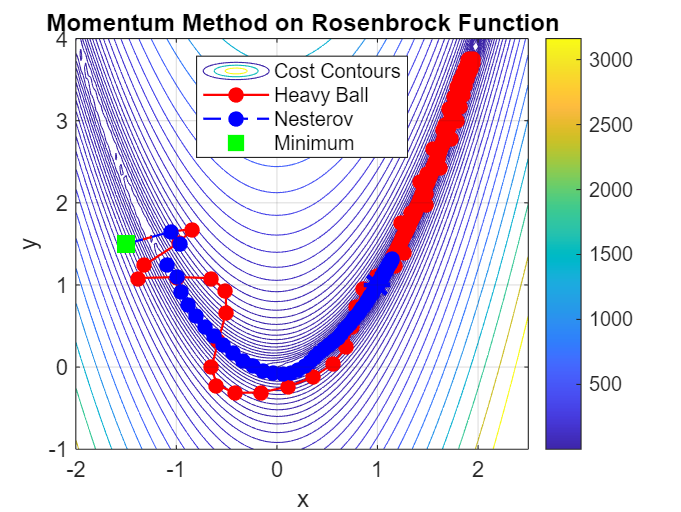

% Create a contour plot of the Rosenbrock function
figure;
[X, Y] = meshgrid(-2:0.05:2.5, -1:0.05:4);
Z = (1-X).^2 + 100*(Y-X.^2).^2;
contour(X, Y, Z, logspace(0, 3.5, 30));
hold on;
colorbar;
title('Momentum Method on Rosenbrock Function');
xlabel('x');
ylabel('y');

% Plot the optimization path
plot(x_history(1,:), x_history(2,:), '-or', 'LineWidth', 1.0, 'MarkerFaceColor', 'r');
plot(x_history_N(1,:), x_history_N(2,:), '--ob', 'Linewidth', 1.0, 'MarkerFaceColor','b');

% Mark start and end points
plot(x0(1), x0(2), 'sg', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
plot(x_final(1), x_final(2), '*b', 'MarkerSize', 12, 'LineWidth', 2);
legend('Cost Contours', 'Heavy Ball', 'Nesterov', 'Minimum', 'Location','north');

hold off
grid on;